# **TU: Multilevel One-Dimensional Wavelet Analysis**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

**Wavelet Decomposition**

[c,l] = wavedec(x,n,wname) returns the wavelet decomposition of the 1-D signal x at level n using the wavelet wname. 

The output decomposition structure consists of the wavelet decomposition vector c and the bookkeeping vector l, which contains the number of coefficients by level.

## Include path

addpath('../../../Library')  

## **Example : **

## **Wavelet Decomposition of Simple sinewaves **Dataset

Perform a 3-level wavelet decomposition of the signal using the order 2 Daubechies wavelet. 

Extract the coarse scale approximation coefficients and the detail coefficients from the decomposition.

[`A`](https://kr.mathworks.com/help/wavelet/ref/appcoef.html#mw_e10ffe10-675d-4725-9f6b-ea715d1083b4) `= appcoef(`[`C`](https://kr.mathworks.com/help/wavelet/ref/appcoef.html#mw_1b4c6e5e-4972-4fe7-8a8a-20e63e8a74bb)`,`[`L`](https://kr.mathworks.com/help/wavelet/ref/appcoef.html#mw_5fd7abad-6766-4f00-a884-43b3beeed306)`,`[`wname`](https://kr.mathworks.com/help/wavelet/ref/appcoef.html#mw_b23bcf36-9f59-444a-9269-85127cf9f69f)`)` returns the approximation coefficients at the **coarsest** scale using the wavelet decomposition structure [`C`,`L`] of a 1-D signal

[`D`](https://kr.mathworks.com/help/wavelet/ref/detcoef.html#mw_9429c5e3-5197-4659-a1f2-10cd299ce481) `= detcoef(`[`C`](https://kr.mathworks.com/help/wavelet/ref/detcoef.html#mw_d5d1a99e-b106-4d5a-9002-4bd0911c2675)`,`[`L`](https://kr.mathworks.com/help/wavelet/ref/detcoef.html#mw_810f8811-65d3-4d9d-bae0-2d9067a97e1d)`,`[`N`](https://kr.mathworks.com/help/wavelet/ref/detcoef.html#mw_9acca19b-b0af-4d64-952d-16594697e7b7)`)` extracts the detail coefficients at the level or levels specified by `N`.

#### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 1000;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
Fa=[1 10 50 100]
X=0;
for i=1:2
    X =X+sin(2.0*pi*Fa(i)*t);
end

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')


% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xm = X+noise; 


% Plot signals
figure()
plot(1000*t,X, 1000*t,Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 100])

#### Wavelet Decomposition 


[c,l] = wavedec(X,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);


Plot the coefficients.

figure()
subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')




## **Exercise :  Wavelet Decomposition and Coefficient Energy**

## Algorithms

## 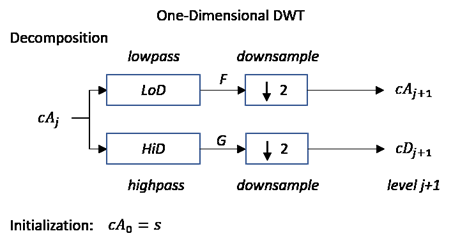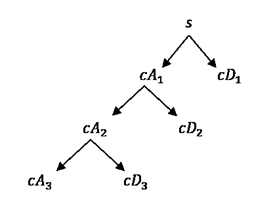

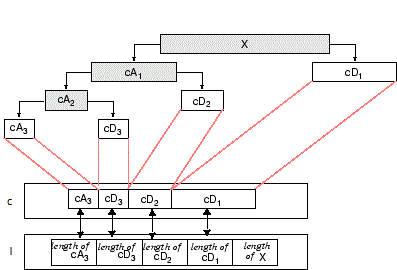

#### Load  Signals 

load sumsin 

figure
plot(sumsin)
title('Signal')

#### Wavelet Decomposition

- use level=3,  db2 wavelet 

%%% wavelet decomposition
% Add your code here
% [c,l] = wavedec(_____________);

approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);


%%% Calculate energy for each coefficient
% Ea: approximation coefficient energy
% Ed: detail coefficient energy

% Add your code here
%[Ea,Ed] = ______________

Plot the coefficients.

figure
subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')


## Example : Wavelet Families

`[`[`LoD`](https://kr.mathworks.com/help/wavelet/ref/wfilters.html#d123e125694)`,`[`HiD`](https://kr.mathworks.com/help/wavelet/ref/wfilters.html#d123e125714)`,`[`LoR`](https://kr.mathworks.com/help/wavelet/ref/wfilters.html#d123e125734)`,`[`HiR`](https://kr.mathworks.com/help/wavelet/ref/wfilters.html#d123e125754)`] = wfilters(`[`wname`](https://kr.mathworks.com/help/wavelet/ref/wfilters.html#d123e125419)`)` returns the four lowpass and highpass, decomposition and reconstruction filters associated with the orthogonal or biorthogonal wavelet `wname`.

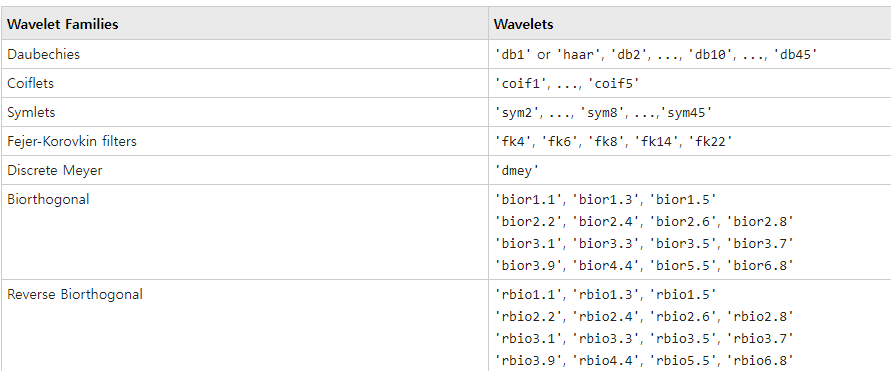


wname = 'db3';
[LoD,HiD,LoR,HiR] = wfilters(wname); 
figure
subplot(2,2,1)
stem(LoD)
title('Decomposition Lowpass Filter')
subplot(2,2,2)
stem(HiD)
title('Decomposition Highpass Filter')
subplot(2,2,3)
stem(LoR)
title('Reconstruction Lowpass Filter')
subplot(2,2,4)
stem(HiR)
title('Reconstruction Highpass Filter')
xlabel(['The four filters for ',wname])

# Wavelet Packet Decomposition

This is used more often in machinery vibration analysis

[Read here for more detail](https://kr.mathworks.com/help/wavelet/ug/wavelet-packets-decomposing-the-details.html)

First level j=0,  frequency axis is divided by [0~Fs/2], [Fs/2~Fs]

At each level, *j*, the frequency axis [0,1/2] is divided into 2*j* subbands. The subbands in hertz at level *j* are approximately

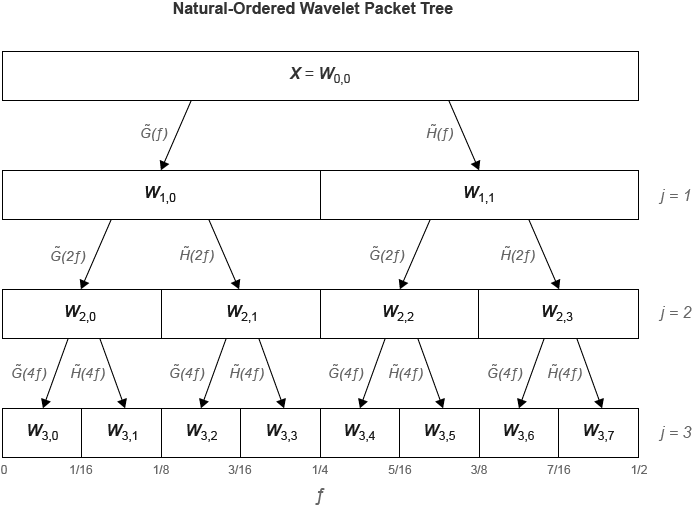

## Data Generation

Fs: the data are sampled at 1 kHz. 

Two intermittent sine waves with frequencies of 150 and 200 Hz in additive noise.

dt = 0.001;
t = 0:dt:1-dt;
x = cos(2*pi*150*t).*(t>=0.2 & t<0.4)+sin(2*pi*200*t).*(t>0.6 & t<0.9);
y = x+0.05*randn(size(t));


## Exercise: Wavelet Packet Decomposition 

In the corresponding wavelet packets situation, each detail coefficient vector is also decomposed into two parts using the same approach as in approximation vector splitting. This offers the richest analysis: the complete binary tree is produced in the one-dimensional case or a quaternary tree in the two-dimensional case.

- Use db1 wavelet, level=3 for wavelet packet

%%% Wavelet Packet Decomp
xin=x;

% Your code goes here
% Use db1 wavelet, level=3 for wavelet packet
% wpt = wpdec(_________________)


plot(wpt)

%%% Energy of each coefficient at TERMINAL node
% Your code goes here
% E = wenergy(________)
